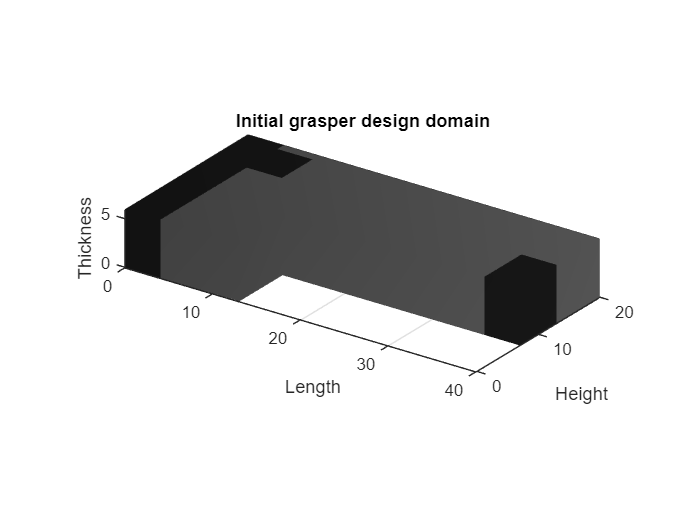

clear;
clc;
close all;

%% Basic model settings

model.nelx = 40;       % Number of elements in X direction
model.nely = 20;       % Number of elements in Y direction
model.nelz = 6;        % Number of elements in Z direction

% Material properties
model.E0 = 2e9;        % Young's modulus [Pa]
model.Emin = 1e-6*model.E0;
model.nu = 0.30;       % Poisson's ratio

% Create the design domain
design = helper("createDesign",model);

% Display the initial design
helper("showDesign",design);

should get a 3D visualization showing your:

- fixed region, 

- input point, 

- output point.

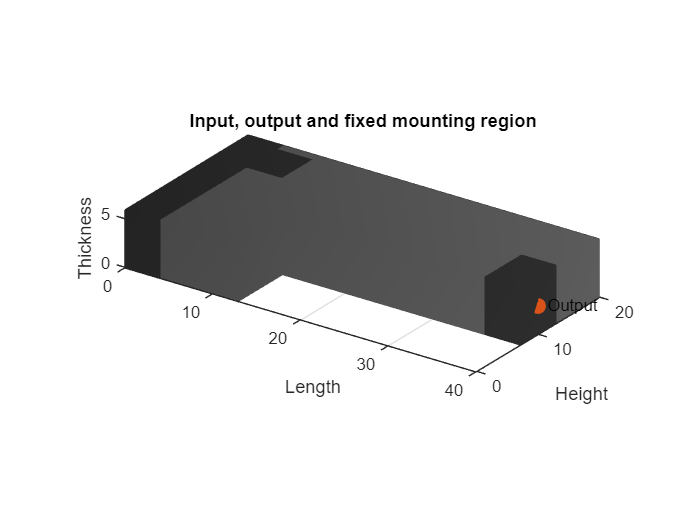

%% Boundary conditions

BC = helper("createBC",model,design);

% Display the boundary conditions
helper("showBC",model,design,BC);

4. Create the TOP settings

%% Topology optimization settings

s.nelx = model.nelx;
s.nely = model.nely;
s.nelz = model.nelz;

% Material
s.E0 = model.E0;
s.Emin = model.Emin;
s.nu = model.nu;

% SIMP parameters
s.penal = 3.0;

% Volume fraction
s.volfrac = 0.40;

% Density filter radius
s.rmin = 2.0;

% Convergence settings
s.maxIter = 50;
s.tolX = 0.01;

% Design and boundary conditions
s.design = design;
s.BC = BC;

5. Run the topology optimization

Iteration   1 | objective -1.00335e-10 | volume 0.393 | change 0.100
Iteration   2 | objective -5.85163e-11 | volume 0.400 | change 0.100
Iteration   3 | objective  1.75162e-10 | volume 0.400 | change 0.100
Iteration   4 | objective -1.48055e-09 | volume 0.400 | change 0.100
Iteration   5 | objective -3.59878e-10 | volume 0.393 | change 0.100
Iteration   6 | objective  1.78252e-10 | volume 0.400 | change 0.100
Iteration   7 | objective  1.49824e-11 | volume 0.386 | change 0.100
Iteration   8 | objective -7.71272e-11 | volume 0.386 | change 0.100
Iteration   9 | objective -1.11104e-10 | volume 0.380 | change 0.100
Iteration  10 | objective -2.11917e-10 | volume 0.375 | change 0.100
Iteration  11 | objective -3.35860e-10 | volume 0.375 | change 0.100
Iteration  12 | objective -4.95597e-10 | volume 0.378 | change 0.100
Iteration  13 | objective -8.09366e-10 | volume 0.368 | change 0.100
Iteration  14 | objective -2.22846e-09 | volume 0.356 | change 0.100
Iteration  15 | objective -6.03785

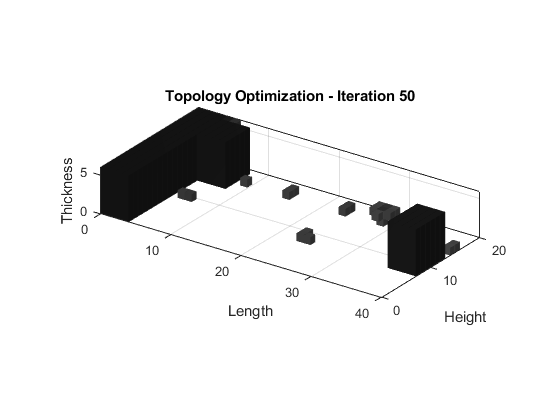

%% Run topology optimization

s.animation.show = true;
s.animation.store = true;
s.animation.threshold = 0.50;
s.animation.every = 1;

result = top3d(s);

6. Display the final topology

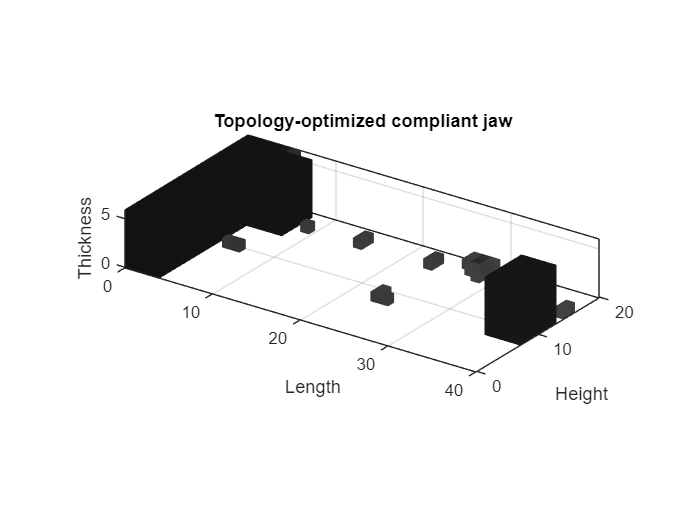

%% Display final topology

threshold = 0.50;

helper("showTopology",result.xPhys,threshold);

7. Plot the optimization history

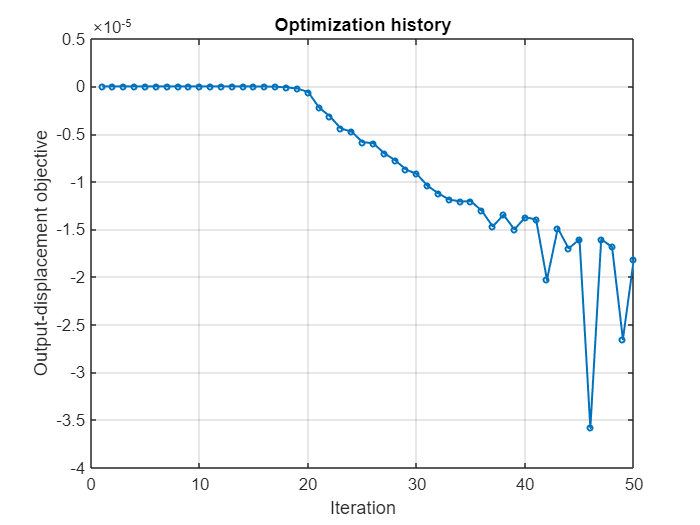

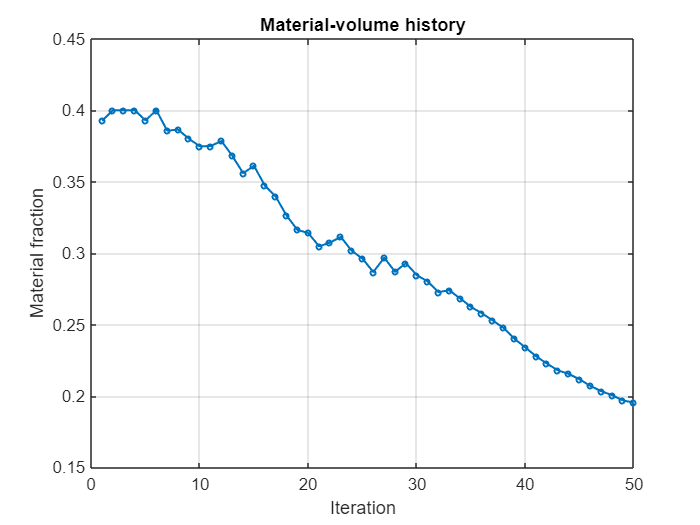

%% Plot convergence history

helper("plotHistory",result);

8. Check the basic displacement response

%% Basic displacement response

displacement = linspace(0,1,20);

response = helper("forceResponse",result,displacement);

Normalized input stiffness: 14264.131471
Output/input displacement ratio: -0.286239


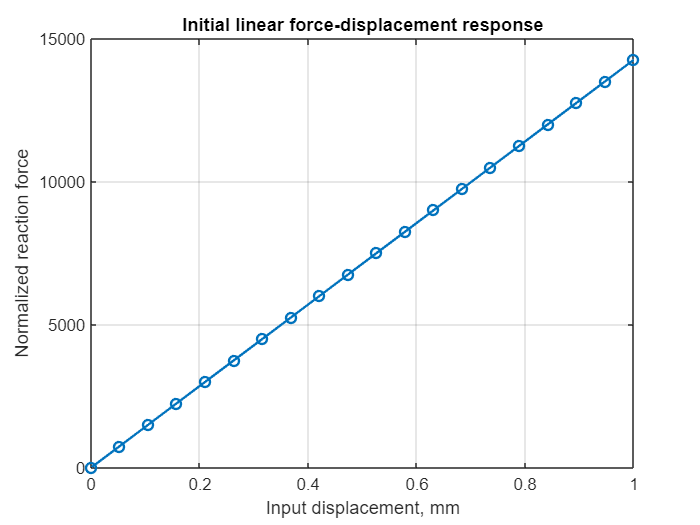


helper("plotForceResponse",response);

9. Export the optimized topology as STL

%% Export STL

elementSize = 1.0;   % Element size in your chosen geometry units
fileName = "optimized_grasper.stl";

helper("exportSTL", ...
       result.xPhys, ...
       threshold, ...
       elementSize, ...
       fileName);